# **DANE**

## Skrzydło

clear sum
clear all
cr = 33.3 %[ft]
ct = 6.5 %[ft]
b = 156.1 %[ft]
lambda_w=ct/cr
AR = 7.844    
b=156.1 %[ft]
Lambda_LE=34 %[deg]
Lambda_LE_rad = deg2rad(Lambda_LE)
MAC = 22.9 %[ft]
S = 3106 %[ft^2]
y_MAC = 30.266 %[ft]
x_MAC = 20.414 %[ft]
Lambda_025 = 30.484 %[deg]
Lambda_025_rad = deg2rad(Lambda_025) %[rad]
Lambda_05 = 26.694 %[deg]
Lambda_05_rad = deg2rad(Lambda_05) %[rad]

## Usterzenie poziome

lambda_H = 0.311
AR_H = 5.267
b_H = 61.1 %[ft]
Lambda_LEH = 38 %[deg]
Lambda_LEH_rad = deg2rad(Lambda_LEH) %[rad]
MAC_H = 12.669 %[ft]
S_H = 708.760 %[ft^2]
y_MAC_H = 12.597 %[ft]
x_MAC_H = 9.842 %[ft]
Lambda_025H = 34.272 %[deg]
Lambda_025H_rad = deg2rad(Lambda_025H) %[rad]
Lambda_05H = 30.183 %[deg]
Lambda_05H_rad = deg2rad(Lambda_05H) %[rad]

## Usterzenie pionowe

lambda_V = 0.323
AR_V = 3.846
b_V = 29.9 %[ft]
Lambda_LEV = 45 %[deg]
Lambda_LEV_rad = deg2rad(Lambda_LEV)
MAC_V = 16.905 %[ft]
S_V = 464.945 %[ft^2]
y_MAC_V = 12.402 %[ft]
x_MAC_V = 12.402 %[ft]
Lambda_025V = 40.927 %[deg]
Lambda_025V_rad = deg2rad(Lambda_025V) %[rad]
Lambda_05V = 36.283 %[deg]
Lambda_05V_rad = deg2rad(Lambda_05V) %[rad]


## Dane lotu

- dla dwóch wysokosći

- dla czterech prędkości

height = [0., 20000.] %[ft]
mach = [0., 0.4, 0.5, 0.6] %UWAGA CZTERY PREDKOŚCI

## Dane środowiskowe

temperature = [288.15 248.526] %[K]
pressure = [2116.23 972.499] %[lbf/ft^2]
density = [0.00237717, 0.00126659] %[slug/ft^3]
v_sound = [1113.45, 1036.85] %[ft/s]
dynamic_visosity = [3.78456E-07, 3.35735E-07] %[slug/(ft*s)]
gravity_acceleration = [32.17, 32.17] %[ft/s^2]

dyn_press_help1 = [v_sound.' v_sound.' v_sound.' v_sound.'].*[mach; %v_sound *mach
                                                              mach]

dynamic_pressure = 0.5*[density.' density.' density.' density.'].*dyn_press_help1.*dyn_press_help1 %[lbf/ft^2]
% dynamic_pressure = 0.5*density*(mach.*v_sound).^2 %[lbf/ft^2] ?

## Dane masowe

Weight = 270000 %[lbf]
Ixx = 4533982 %[slug*ft2]
Iyy = 7699141   %[slug*ft2] 
Izz12 = 12090750 %[slug*ft2]
Ixz = 1094574 %[slug*ft2]
Mass = 8391,856431 %[slug]

L = 155 %[ft]

## Dane lotu z suplementu Żugaja

alfa_0 = -1,4 %deg
alfa_0_rad = deg2rad(alfa_0) %rad

Eps_0 = 0
Eps_w = 2 %deg <--- podstawiasz w stopniach

e_os = 0.8
C_L_0H = 0

a_0w = -1.4 %[deg]  czy tu w stopniach????

eta_H = 0.85
eta_v = 0.8
eta_w = 0.8

f = 35 %[ft^2]

i_H1 = 0 %[deg] [rad]

C_Du = 0

## Inne dane geometryczne

x_WHR = 79.6 % [ft]
x_CG = 0.25*MAC % [ft]

# **OBLICZENIA**

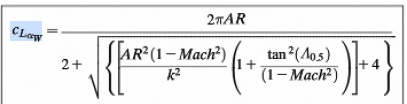 ale jeszcze razy eta_w!!!!!!!!

k = 1 + ((8.2 - 2.3*Lambda_LE_rad)-AR*(0.22 - 0.153*Lambda_LE_rad))/100

p1 = ((AR^2)*(1-mach.*mach))/(k^2)
p2 = 1 + (tan(Lambda_05_rad)^2)./(1-mach.*mach)


C_LaW = eta_w*(2*pi*AR)./(2+sqrt(4+p1.*p2))

#### CLalfaH

k_H = 1+((8.2-2.3*Lambda_LEH_rad)-AR_H*(0.22-0.153*Lambda_LEH_rad))/100

C_LaH = eta_H*(2.*pi.*AR_H./(2+sqrt(AR_H^2.*(1-mach.^2)./k_H^2.*(1+tan(Lambda_05H_rad)^2./(1-mach.^2))+4)))

# 

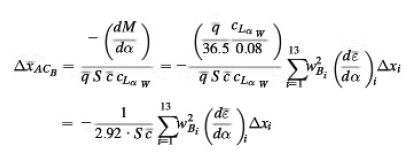

%%%%%%%%   X_AC_W   %%%%%%%%%%%%
K1 = 1.45
K2 = 0.57865

p3 = [0.815 0.79 0.76 0.73] %X_AC/C_R z wykresu 2.27

%x_AC =  p3 * cr
%%%%%% Dziki wzór Janeczka %%%%%%%%%
random_zmienna_pomocnicza = C_LaH./C_LaW.*eta_H* S_H/S.*(1-dEps_da_Mach)
x_AC = (x_AC_WB + random_zmienna_pomocnicza.*x_AC_H)./(1+random_zmienna_pomocnicza)

x_AC_W = K1.*(p3 - K2)

x_AC_dash = x_AC/MAC

%%%%%%%%   d X_AC_B_dash   %%%%%%%%%%%%
pomoc1 = -1/(2.92*S*MAC)

%%%% GIGA SUMA
xh = 59.3093 %[ft]

xi = [47.33 47.33 47.33 47.33;
      36.75 36.75 36.75 36.75;
      26.25 26.25 26.25 26.25;
      15.75 15.75 15.75 15.75;
      5.25 5.25 5.25 5.25;
      24.91 24.91 24.91 24.91;
      8.3 8.3 8.3 8.3;
      5.75 5.75 5.75 5.75;
      17.25 17.25 17.25 17.25;
      28.75 28.75 28.75 28.75;
      40.25 40.25 40.25 40.25;
      51.75 51.75 51.75 51.75;
      63.3 63.3 63.3 63.3]
     
wbi = [8.4 8.4 8.4 8.4;
       14.84 14.84 14.84 14.84;
       16.45 16.45 16.45 16.45;
       16.46 16.46 16.46 16.46;
       16.46 16.46 16.46 16.46;
       16.46 16.46 16.46 16.46;
       16.46 16.46 16.46 16.46;
       16.46 16.46 16.46 16.46;
       16.46 16.46 16.46 16.46;
       16.28 16.28 16.28 16.28;
       14.19 14.19 14.19 14.19;
       9.64 9.64 9.64 9.64;
       5.18 5.18 5.18 5.18]

dxi = [10.66 10.66 10.66 10.66;
       10.5 10.5 10.5 10.5;
       10.5 10.5 10.5 10.5;
       10.5 10.5 10.5 10.5;
       10.5 10.5 10.5 10.5;
       16.6 16.6 16.6 16.6;
       16.6 16.6 16.6 16.6;
       11.5 11.5 11.5 11.5;
       11.5 11.5 11.5 11.5;
       11.5 11.5 11.5 11.5;
       11.5 11.5 11.5 11.5;
       11.5 11.5 11.5 11.5;
       11.63 11.63 11.63 11.63]
x_cf = xi/ cr




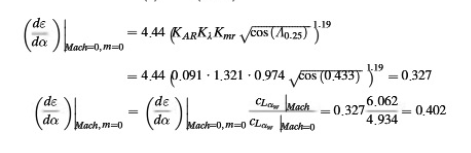

K_AR = (1/AR)-1/(1+AR^1.7)
K_lambda = (10 - 3*lambda_w)/7

z_WH = 6.6 %[ft]
m = 2* z_WH/b

x_WH = 75.7 %[ft]
r = 2 * x_WH/b
K_mr0 = (1-0.5*0)/(r^0.33) %m=0 !!!!!!!!!
K_mr = (1 - 0.5*m)/(r^0.33)

dEps_da_Mach0_m0 = 4.44*(K_mr0*K_lambda*K_AR*sqrt(cos(Lambda_025_rad)))^1.19

dEps_da_m0 = dEps_da_Mach0_m0*C_LaW/C_LaW(1)

dEps_da = [1.11 1.11 1.11 1.11;
           1.16 1.16 1.16 1.16;
           1.24 1.24 1.24 1.24;
           1.405 1.405 1.405 1.405;
           3.86 3.86 3.86 3.86
           ]
for i=6:13
    dEps_da = [dEps_da; (xi(i, :)/xh).*(1-dEps_da_m0)]
end




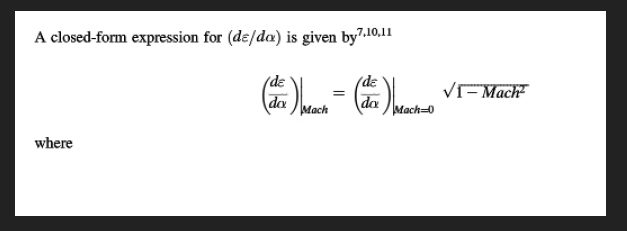

%%%%%% dEps_da_Mach
%dEps_da_Mach =(4.44*(K_mr*K_lambda*K_AR*sqrt(cos(Lambda_025_rad)))^1.19)*sqrt(1 -mach.*mach)
%ten wzór podobno fu

dEps_da_Mach  = dEps_da_Mach(1)*C_LaW/C_LaW(1)


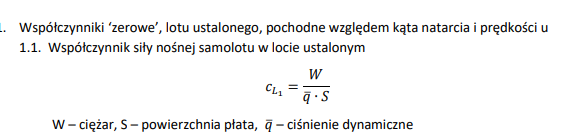

C_L1 = Weight./(dynamic_pressure*S)

C_La=C_LaW + C_LaH.*eta_H*(S_H/S).*(1-dEps_da_Mach)

**Epsilon:**

Nie mogę znaleźć wzorów ale wierzę, że Michał to dobrze wpisał:

Wzór jest przepisany z czyjejś formuły w Excelu XDD \Michał

Eps = dEps_da_Mach.*(C_L1 - (-0.024))./(C_La)


%%%%%% d_X_AC_B ostatecznie %%%%%%
d_X_AC_B = pomoc1*sum(wbi.*wbi.*dEps_da.*dxi)


x_AC_WB = x_AC_W + d_X_AC_B

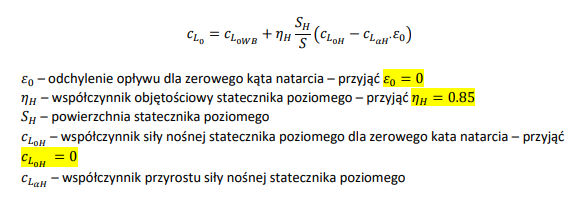

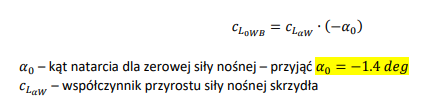

C_L0WB = C_LaW * (-alfa_0_rad)
C_L0 = C_L0WB + eta_H * (S_H/S) * (C_L_0H - C_LaH*Eps_0)

mach_pom = [mach;
            mach]
C_Lu = ((mach_pom.*mach_pom)./(1-(mach_pom.*mach_pom))).*C_L1 %poprawione :)

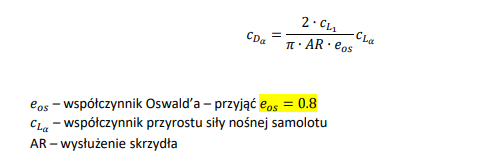

C_Da = ((2*C_L1)./(pi()*AR*e_os)).*C_La

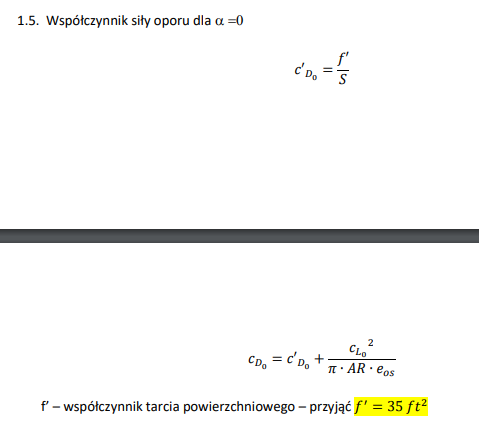

C_D0_pochodna = f/S
C_D0 = ((C_L0.*C_L0)/(pi()*AR*e_os)) + C_D0_pochodna

**C_m0W**

cm0r = 0
cm0t = 0
d_Cm0_Eps_w = -0.00577 %powinien być na minusie???????????????
C_m0W = ((AR*cos(Lambda_025_rad)^2)/(AR+2*cos(Lambda_025_rad)^2))*((cm0r+cm0t)/2)+(d_Cm0_Eps_w)*Eps_w

**C_m0B**

k2_k1 = 0.92355
i_cl = [-6.33 -0.846 0.289 0 0 0 0 0 -0.633 -3.79 -3.638 -1.927 -1.379]
C_m0B = (k2_k1/(36.5*S*MAC))*sum(wbi(:, 1).*wbi(:, 1).*(a_0w+i_cl.').*dxi()) %czy tu ma być w stopniach?????

**C_m0WB**

C_m0_ratio = [1 1.03074 1.0715 1.12919]
C_m0_WB = (C_m0B+C_m0W).*C_m0_ratio

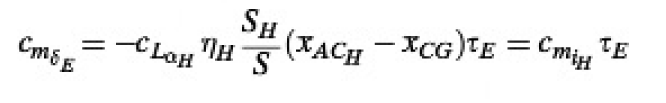

tau_e = 0.38 %fig 3.7
x_AC_H =x_WHR + x_MAC_H + (MAC_H/4) - x_MAC
x_AC_H_dash = x_AC_H/MAC
x_CG_dash = x_CG/MAC

C_mdelta_E = -C_LaH*eta_H*(S_H/S)*(x_AC_H_dash - x_CG_dash)*tau_e

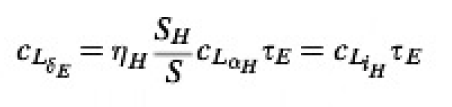

c_Ldelta_E = eta_H*(S_H/S)*C_LaH*tau_e

**C_LiH**

C_LiH = eta_H*(S_H/S).*C_LaH

**C_LWB**

C_L_WB = C_LaW*(-alfa_0_rad)

**C_Lq**

B= sqrt(1-mach.*mach.*(cos(Lambda_025_rad)^2))
C_LqW_Mach0 = (0.5 +2* abs(x_AC_W-x_CG_dash))*C_LaW(1)
C_LqW = (((AR + 2*cos(Lambda_025_rad))./(AR*B+2*cos(Lambda_025_rad)))).* C_LqW_Mach0

C_LqH = 2 * C_LaH * eta_H * (S_H/S)*(x_AC_H_dash - x_CG_dash)

C_Lq = C_LqW+C_LqH

**C_m0**

C_m0 = C_m0_WB + (x_CG_dash-x_AC_WB).*(C_L_WB) % wyszły ujemne, nie wiem czy git

**C_ma**

C_ma = C_LaW.*(x_CG_dash-x_AC_WB)-C_LaH*eta_H*(S_H/S).*(1-dEps_da_Mach).*(x_AC_H_dash-x_CG_dash)

**C_mu**

%dx_AC_w_dMach = -0.435 %h = 0 i h = 20000 dla obu jest tyle samo!!!!

dx_AC_w_dMach=K1.*p3./MAC
C_mu = -C_L1.*dx_AC_w_dMach

**C_m_alpha_dot**

C_m_alpha_dot = -2* C_LaH *(S_H/S)*((x_AC_H_dash-x_CG_dash)^2).*dEps_da_Mach

**C_miH**

C_miH = -C_LaH*eta_H*(S_H/S)*(x_AC_H_dash-x_CG_dash)

**C_Dq**

C_Dq = 0

**C_m_qW**

C  = ((AR*(0.5*abs(x_AC_W - x_CG_dash)+2*abs(x_AC_W-x_CG_dash).^2))./(AR+2*cos(Lambda_025_rad)))+(1/24)*(((AR^3)*tan(Lambda_025_rad).^2)./(AR+6*cos(Lambda_025_rad)))+1/8
Kq = 0.78
C_mqW_mach0 = - Kq *C_LaW(1)*cos(Lambda_025_rad)*C
pomoc2 = ((AR^3)*tan(Lambda_025_rad)^2)./(AR.*B+6*cos(Lambda_025_rad))
pomoc3 = ((AR^3)*tan(Lambda_025_rad)^2)/(AR+6*cos(Lambda_025_rad))
C_mqW = ((pomoc2+(3./B))./(pomoc3+3)).*C_mqW_mach0

**C_m_qH**

C_m_qH = -2*C_LaH*eta_H*(S_H/S).*(x_AC_H_dash-x_CG_dash).*(x_AC_H_dash-x_CG_dash)

**C_mq**

C_mq = C_mqW+C_m_qH

**C_La_dot**

C_La_dot = 2*C_LaH*eta_H*(S_H/S).*(x_AC_H_dash-x_CG_dash).*dEps_da_Mach

**alfa_1**

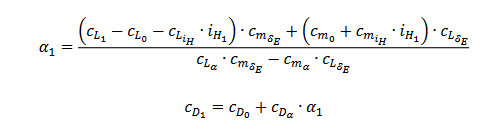

alfa_1 = ((C_L1-C_L0).*C_mdelta_E+(C_m0).*c_Ldelta_E)./(C_La.*C_mdelta_E - C_ma.*c_Ldelta_E) %pls spojrz na to czy ok - według mnie ok ~ Łukasz

**C_D1**

C_D1 = C_D0 + C_Da.*alfa_1

**delta_E1**

delta_E1 = (-(C_L1-C_L0).*C_ma-(C_m0).*C_La)./(C_La.*C_mdelta_E-C_ma.*c_Ldelta_E)